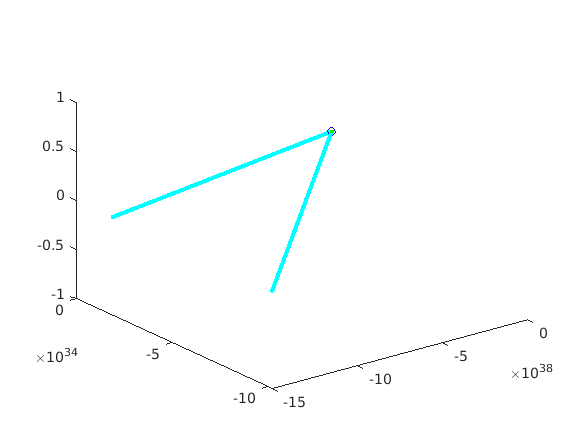

global G m;
G = 6.67428E-11; % m3 kg-1 s-2
 
mS = 1.989E30; % kg - masa de la Sol
rS = 6.96340E8; % radio del Sol m





 mU = 8.683E25; % kg - masa del Urano
 mN = 1.024E30; % kg - masa del Neptuno
m = [mS; mU; mN];
rN = 2.4622E7; % radio de Neptuno m
rU = 2.5362E7; % radio de Urano m
hU = 2.871E12; % altura Urano m
hN = 4.498E12; % altura Neptuno m
ds1 = rU + rS + hU; % distancia entre centros de masa
ds2 = rN + rS + hN; % distancia entre centros de masa
r0 = [ [0;0;0]; [ds1;0;0];  [ds2;0;0]]; % [rS; rU]
Ts1 = 164*365*24*60*60; % periodo en s
Ts2 = 84*365*24*60*60; % periodo en s
ws1 = 2*pi/Ts1; % velocidad angular
vs1 = ws1*ds1; % velocidad tangencial sqrt(G * mS/ds)
ws2 = 2*pi/Ts2; % velocidad angular
vs2 = ws2*ds2; % velocidad tangencial sqrt(G * mS/ds)
v0 = [ [0;0;0]; [0;vs1;0]; [0;vs2;0] ]; % [vT; vs]

nv = 1; % número de vueltas
tf1 = nv*Ts1;
tf2 = nv*Ts2;
h = 24*60*60; % 60 s = 1 minuto 

y0 = [r0;v0];
fhandle = @f; % creation of the function handle of a named function
[t2,y2] = RK4(fhandle,y0,0,tf1,h); 

plot3(y2(1,:),y2(2,:),y2(3,:),'ob');
hold on;
plot3(y2(4,:),y2(5,:),y2(6,:),'.c');

plot3(y2(7,:),y2(8,:),y2(9,:),'.g');
grid minor;

function ydot = f(~,y)
 global G m;
 r = y(1:9); % vectores de posición rS y rU y rN
 v = y(10:18);
 dr1 = r(4:6) - r(1:3); % dr va de la Sol Urano
 dr2 = r(7:9) - r(1:3); % dr va de la Sol Neptuno
 dr3 = r(7:9) - r(4:6); % dr va de la Urano Neptuno
 u1 = dr1 / norm(dr1);
 u2 = dr2 / norm(dr2);
 u3 = dr3 / norm(dr3);
 dr21 = norm(dr1)^2;
 dr22 = norm(dr2)^2;
 dr23 = norm(dr3)^2;
 F1 = (G*m(1)*m(2)/dr21) * u1;
 F2 = (G*m(1)*m(3)/dr22) * u2;
 F3 = (G*m(2)*m(3)/dr23) * u3;
 a = [F1+F2/m(1); -F2-F3/m(2); -F3-F1/m(3)]; % par acción - reacción; tercera ley de Newton
 ydot = [v;a];
end




function [t,y] = RK4(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    m = length(y0);
    y = zeros(m,n);
    y(:,1) = y0;
    for i = 1:n-1
        k1 = f(t(i),y(:,i));
        k2 = f(t(i)+(1/2)*h,y(:,i)+(1/2)*k1*h);
        k3 = f(t(i)+(1/2)*h,y(:,i)+(1/2)*k2*h);
        k4 = f(t(i)+h,y(:,i)+k3*h);
        y(:,i+1) = y(:,i) + (k1+2*k2+2*k3+k4)/6 *h;
    end
end


function y0 = sumaV(y0,y1)
    n = length(y0);
    for i = 1:n
        if(y0(i)<0 && y1(i)<0)
            y0(i)=y0(i)+abs(y1(i));
        else
            y0(i)=y0(i)+abs(y1(i));
        end
    end
end